# ハイブリッドロケット ロール制御ハンズオン

**進め方**

- 機体と環境の諸元を決める

- ロール軸の設計点を決め、制御ゲインを選ぶ

- 1DOF のロール運動モデルで安定余裕を確認する

- 6DOF で飛ばして、設計が実飛行で成立するか見る

**単位の約束** すべて SI 単位、角度は rad。表示のときだけ deg に換算する。

**座標系** 慣性基準は UEN（x = Up, y = East, z = North）。鉛直姿勢が pitch = 0 に なるので、鉛直上昇中にオイラー角の特異点に近づかない。

clc,clear,close all

## 環境

風は **空気の速度ベクトル** で与える。UEN なので [0; 5; 0] は空気が東へ動く、 つまり西風のこと。東から吹く風は y 成分を負にする。 

environment_g    = 9.80665;  % 重力加速度[m/s^2]
environment_wind = [0; 3; 0]; % 定常風[m/s]

## 機体の諸元

全長と直径から代表面積が決まる。質量と慣性は燃焼前後の2点を与え、 ブロック内部で推進剤の消費に応じて補間される。

rocket_length   = 2.80;   % 全長 [m]
rocket_diameter = 0.18;   % 直径 [m]

rocket_mass0      = 22.0; % 全備時質量[kg]
rocket_massDry    = 16.5; % 乾燥時質量[kg]
rocket_inertia0   = diag([0.42, 8.6, 8.6]); % 全備時慣性[kgm^2]
rocket_inertiaDry = diag([0.29, 6.9, 6.9]); % 乾燥時慣性[kgm^2]

重心と空力中心は機体後端を原点、機首方向を正として与える。 

rocket_cg0   = [1.45; 0; 0]; % 全備時重心位置[m]
rocket_cgDry = [1.20; 0; 0]; % 乾燥時重心位置[m]
rocket_cp    = [1.10; 0; 0]; % 空力中心[m]

## 推進

推力は一定値、質量流量は Fth/Isp で決まる。

propulsion_thrust     = 1800; % 推力[N]
propulsion_burnTime   = 7.5; % 燃焼時間[s]
propulsion_cutoffTime = propulsion_burnTime;

propulsion_propellant = rocket_mass0 - rocket_massDry; % 推進剤質量[kg]
propulsion_massFlow   = propulsion_propellant / propulsion_burnTime; % 推進剤質量流量[kg/s]

Fth = propulsion_thrust;
Isp = Fth / (propulsion_massFlow*environment_g); % 比推力[s]

## 空力

空力は **無次元係数** で与える。まず対気速度から動圧と姿勢角を作る。


$$\vec{V}_a = \vec{V}_b - \vec{V}_{w}^{\,b}, \qquad \bar{q} = \frac{1}{2}\rho\,|\vec{V}_a|^2$$



$$\alpha = \mathrm{atan2}(w_a,\,u_a), \qquad \beta = \arcsin\left(\frac{v_a}{|\vec{V}_a|}\right)$$


風は機体軸へ変換してから引く。だから **風は迎角と横滑りを通じてのみ効く** 。

aero_refArea   = pi * rocket_diameter^2 / 4; % 機体代表面積[m^2]
aero_refLength = rocket_diameter; % 機体代表長さ[m]

**力の係数**

軸力係数 $C_x = C_{x0}\cos\alpha\cos\beta$

横力係数 $C_y = C_{y0} + C_{y\beta}\,\sin\beta\cos\beta$

法線力係数 $C_z = C_{z0} + C_{z\alpha}\,\sin\alpha\cos\alpha$

Cx_0 = -0.50;
Cy_0 = 0;
Cz_0 = 0;
Cy_b = -10.0;
Cz_a = -10.0;

**モーメントの係数**

ローリングモーメント係数 $C_l = C_{l\delta}\,\delta + C_{lp}\,p$

ピッチングモーメント係数 $C_m = C_{m\alpha}\,\alpha + C_{mq}\,q$

ヨーイングモーメント係数 $C_n = C_{n\beta}\,\beta + C_{nr}\,r$

**力とモーメントの合成**


$$F_{a,x} = \bar{q}\,S\,C_x, \qquad F_{a,y} = \bar{q}\,S\,C_y, \qquad F_{a,z} = \bar{q}\,S\,C_z$$



$$M_{a,x} = \bar{q}\,S\,b\,C_l, \qquad M_{a,y} = \bar{q}\,S\,\bar{c}\,C_m, \qquad M_{a,z} = \bar{q}\,S\,b\,C_n$$


ここへさらに、法線力が空力中心に作用することによるモーメントが加わる。


$$\vec{M}_{\mathrm{tot}} = \vec{M}_a + (\vec{r}_{CP} - \vec{r}_{CG}) \times \vec{F}_a$$


最後の外積が **風見効果** を生む。法線力は空力中心に作用し、それが重心より 後方にあるので機首を相対風へ戻すモーメントになる。 


$$C_{m\alpha}^{\mathrm{eff}} = C_{z\alpha}\,\frac{SM}{\bar{c}}, \qquad C_{n\beta}^{\mathrm{eff}} = -C_{y\beta}\,\frac{SM}{b}$$


ここで $SM = x_{CG} - x_{CP}$ が静安定余裕を表す。

したがって静モーメント係数は 0 にする。

Cm_a = 0;
Cn_b = 0;

**空力による減衰係数**

モデルは無次元化された $q\bar{c}/(2V)$ ではなく、角速度 $q$ [rad/s] に直接 掛けている。つまり $C_{mq}$ は秒の次元を持つ。


$$M_{\mathrm{damp}} = \bar{q}\,S\,\bar{c}\,C_{mq}\,q \quad \mathrm{[N\,m]}$$


値は基準飛行条件で目標の減衰比 $\zeta$ になるように選ぶ。まず静安定から 固有振動数を求め、そこから逆算する。


$$\omega_n = \sqrt{\frac{\bar{q}_{\mathrm{ref}}\,S\,C_{N\alpha}\,SM}{I_{yy}}}$$



$$C_{mq} = -\frac{2\,\zeta\,\omega_n\,I_{yy}}{\bar{q}_{\mathrm{ref}}\,S\,\bar{c}}$$


aero_refSpeed   = 100;
aero_refRho     = 1.225;
aero_refQbar    = 0.5 * aero_refRho * aero_refSpeed^2;
aero_targetZeta = 0.10;
aero_CNalpha = 10;

aero_pitchFreq = sqrt(aero_refQbar * aero_refArea * aero_CNalpha * ...
    (rocket_cg0(1) - rocket_cp(1)) / rocket_inertia0(2, 2));
Cm_q = -2 * aero_targetZeta * aero_pitchFreq * rocket_inertia0(2, 2) ...
    / (aero_refQbar * aero_refArea * aero_refLength);
Cn_r = Cm_q;

## パラシュート

頂点（鉛直速度が 0 を横切る）で自動展開する。抗力はキャノピー位置での 対気速度から計算され、力は取付点を通じて機体に働くとする。 

終端速度は $V = \sqrt{2mg/(\rho\,C_dS)}$ で決まる。

chute_diameter    = 2.0; % パラシュートの直径[m]
chute_Cd          = 1.5; % パラシュートの抗力係数
chute_inflateTau  = 0.5; % パラシュートの展開時定数[s]
chute_attachBody  = [2.60; 0; 0]; % 取付位置
chute_riserLength = 3.0; % パラシュートの紐の長さ

chute_CdS = chute_Cd * pi * chute_diameter^2 / 4; % パラシュートの抗力(動圧乗算前)

## アクチュエータとセンサ

fin_maxDeflection = deg2rad(18); % フィン最大舵角[rad]
fin_maxRate       = deg2rad(120); % フィン最大舵角レート[rad/s]
fin_actuatorTau   = 0.06; % フィンアクチュエーター時定数[s]

sensor_gyroTau     = 0.02; % ジャイロセンサー時定数[s]
sensor_attitudeTau = 0.05; % INU相当の時定数[s]

## ロール軸の設計点

ロール制御は 1DOF で設計する。設計点は **ロール操舵を行う代表的な飛行条件** に合わせる。

roll_design_speed = 221; % 設計点速度[m/s]
roll_design_qbar  = 0.5 * aero_refRho * roll_design_speed^2; % 動圧[Pa]
roll_design_Ixx   = 0.35; % 機体ロール軸イナーシャ[kgm^2]
roll_design_phi   = 0; % 設計点ロール角[rad]
roll_design_p     = 0; % 設計点ロールレート[rad/s]

roll_Lp     = -0.090; % ロールの安定微係数 [N/(rad/s)]
roll_Ldelta = 6.0;    % フィンによる制御微係数 [N/rad]

設計点の値から 6DOF 用の無次元係数へ換算する。ロールモーメントは


$$L = \bar{q}\,S\,b\,\left(C_{l\delta}\,\delta + C_{lp}\,p\right)$$


なので、設計点で $L_\delta\,\delta + L_p\,p$ と一致させる。


$$C_{l\delta} = \frac{L_\delta}{\bar{q}_{\mathrm{des}}\,S\,b}, \qquad C_{lp} = \frac{L_p}{\bar{q}_{\mathrm{des}}\,S\,b}$$


roll_momentScale = roll_design_qbar * aero_refArea * aero_refLength;
Cl_p     = roll_Lp     / roll_momentScale;
Cl_delta = roll_Ldelta / roll_momentScale;

## 制御ゲイン

内側がロールレートの P、外側がロール角の P というカスケードループ。 **ここが調整対象** で、次のセクションの安定余裕を見ながら決める。

controller_outer_Kp = 1;
controller_inner_Kp = 0.01;
controller_outer_maxRateCmd = deg2rad(120); % レート指令値の変化率制限

## 1DOF での安定余裕評価

ロール軸の運動方程式から開ループ伝達関数を組み立てて、ゲイン余裕・位相余裕を見る。 式の中身は evaluation/roll_margin_1dof.m を開くと追える。

--- ロール軸の素の特性 ---
  時定数   Ixx/|Lp|   = 3.89 s
  定常ゲイン Ldelta/|Lp| = 66.7 (rad/s)/rad = 66.67 (deg/s)/deg

--- 安定余裕 ---
  ループ                  GM[dB]   PM[deg]   wc[rad/s]
  フィン指令ループ              51.64     52.31       0.391
  外側ロールループ              27.27     51.47       0.321

--- 閉ループ（phiCmd -> phi）---
  立上り時間 3.93 s / 整定時間 19.49 s / オーバーシュート 16.5 %
  帯域幅 0.53 rad/s


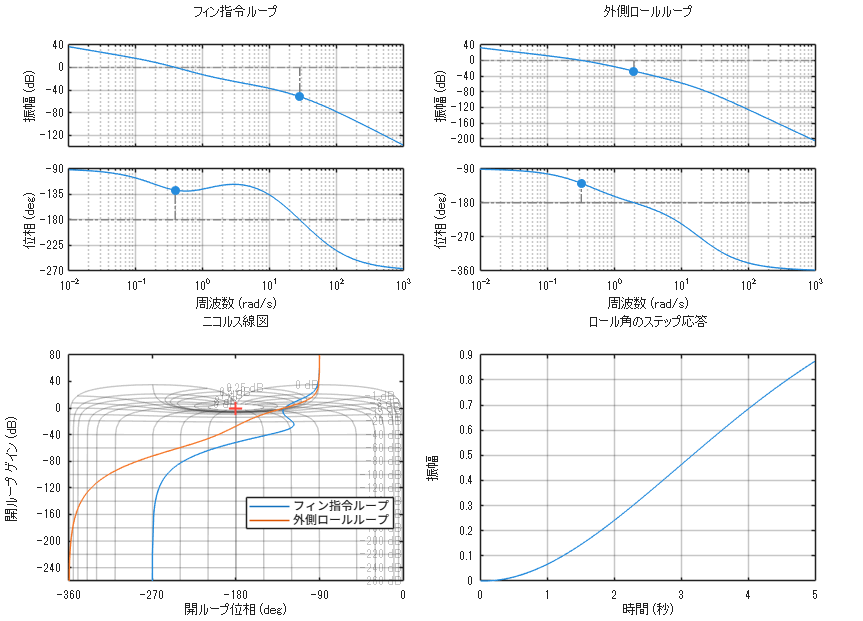


--- 内側ゲインを振ったときのフィン指令ループ ---
  inner_Kp     GM[dB]   PM[deg]   wc[rad/s]
  0.005         57.66     58.49       0.247
  0.010         51.64     52.31       0.391
  0.020         45.62     50.67       0.604
  0.040         39.60     53.46       0.947


roll_margin_1dof

## 指令と初期条件

command_rollStep = deg2rad(20);
command_stepTime = 3.0;

initial_position     = [0; 0; 0];
initial_velocityBody = [0; 0; 0];
initial_euler        = [0; deg2rad(-15); 0];
initial_pqr          = [0; 0; 0];

sim_stopTime  = 800;
sim_fixedStep = 0.01;

## 準備

パス設定、モデルの信号ログ設定、パラメータの過不足チェックをまとめて行う。

CG = rocket_cg0;
CP = rocket_cp;

workshop_setup

--- 設計条件 ---
  代表面積      : 0.025447 m^2 (直径 0.180 m)
  静安定余裕    : 0.350 m (1.94 caliber)
  推力 / 燃焼   : 1800 N / 7.5 s (mdot 7.192 kg/s)
  ロール舵効き  : 6.00 Nm/rad @ qbar 29915 Pa
  ロール指令    : 20.0 deg @ 3.00 s
  傘 CdS        : 4.71 m^2 -> 終端速度 7.5 m/s



## 1DOF の時間応答

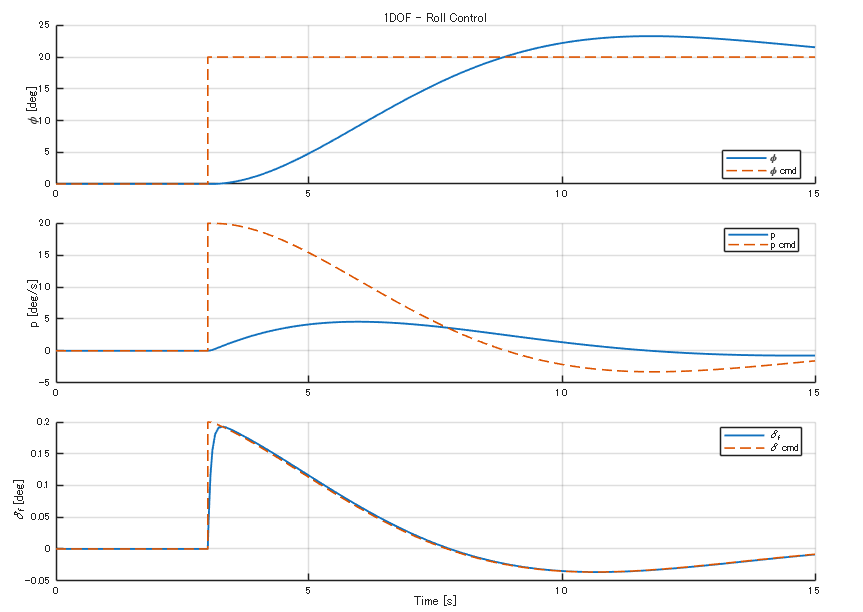

simOut_roll_1dof = workshop_simulate("roll_1dof_model", 15);
workshop_plots(simOut_roll_1dof, "1DOF")

## 6DOF で飛ばす

同じゲインのまま 6DOF に持っていく。

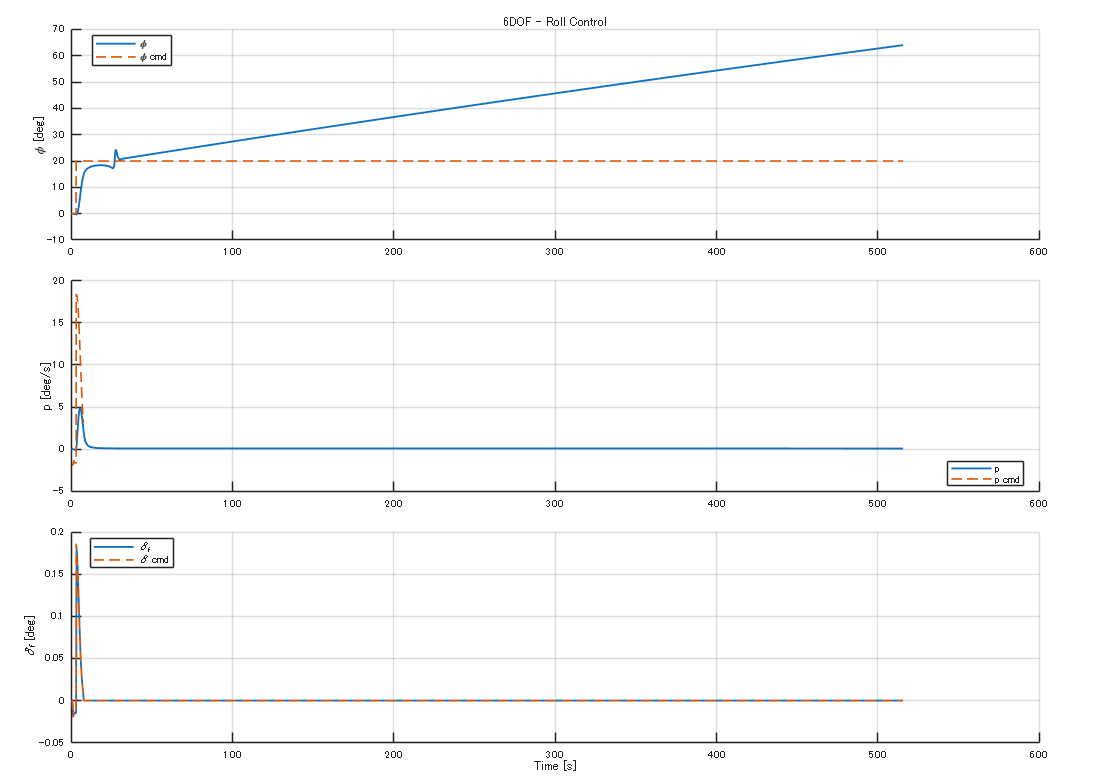

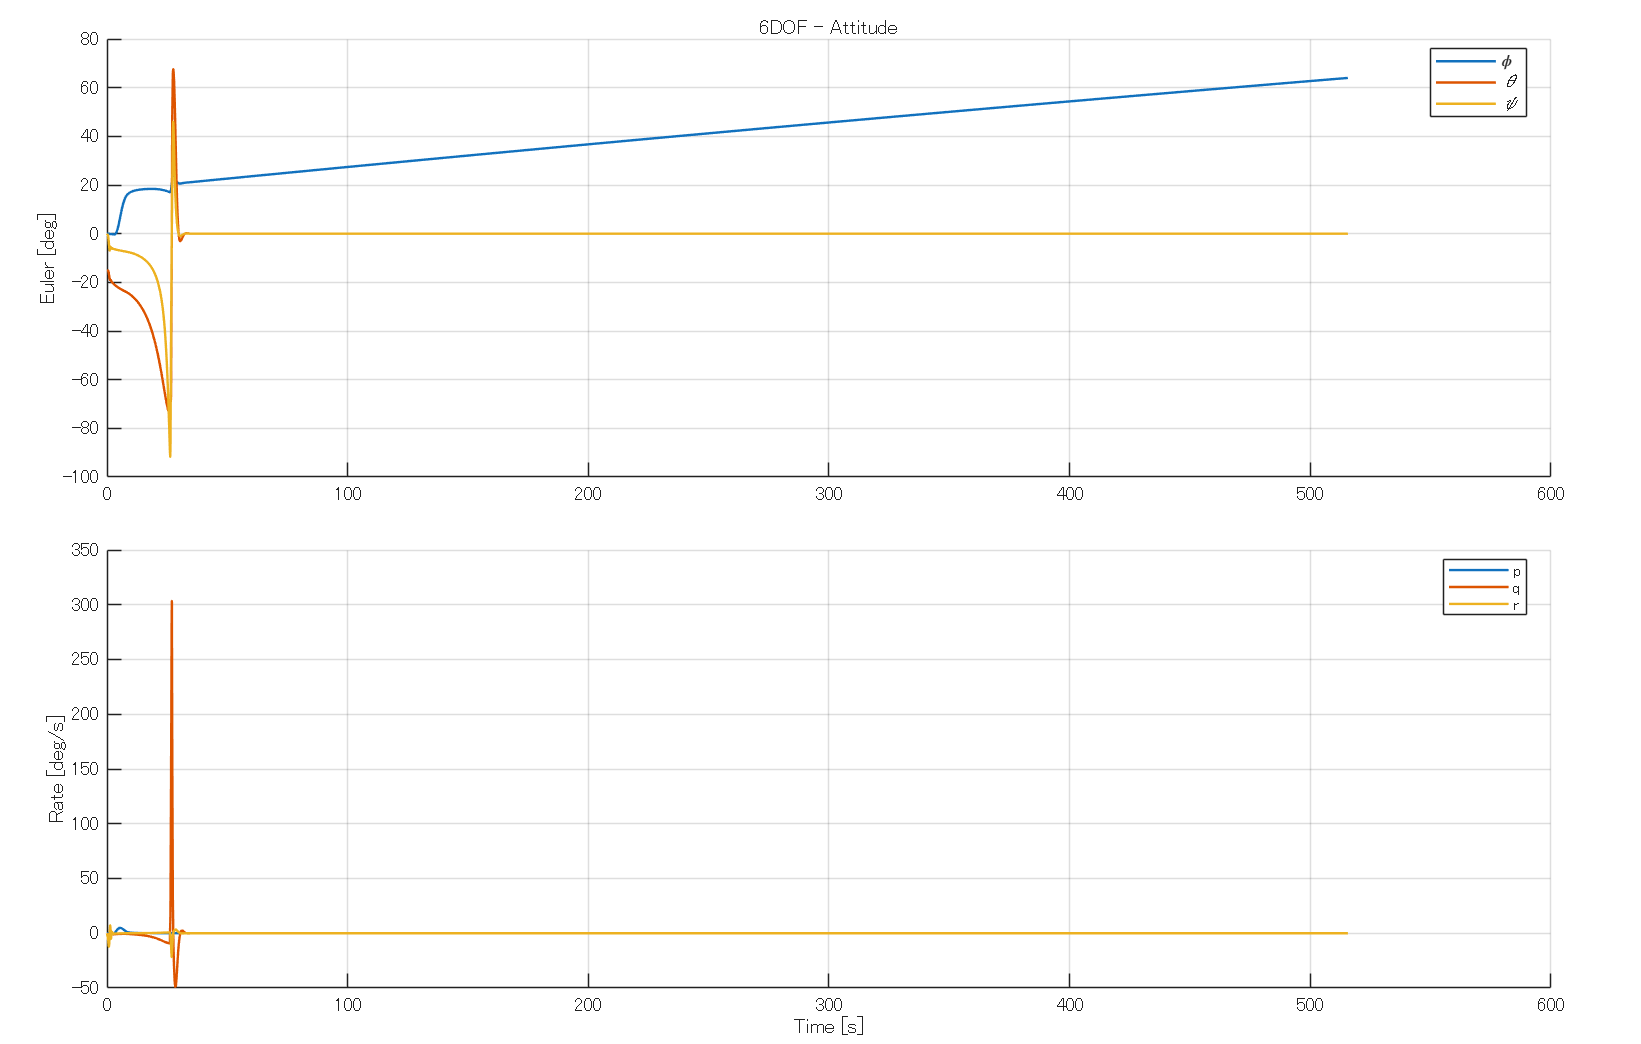

simOut_rocket_6dof = workshop_simulate("rocket_6dof_with_roll_controller");
workshop_plots(simOut_rocket_6dof, "6DOF")

## 飛行アニメーション

PlaybackSpeed を上げるとコマが間引かれて短時間で終わる。

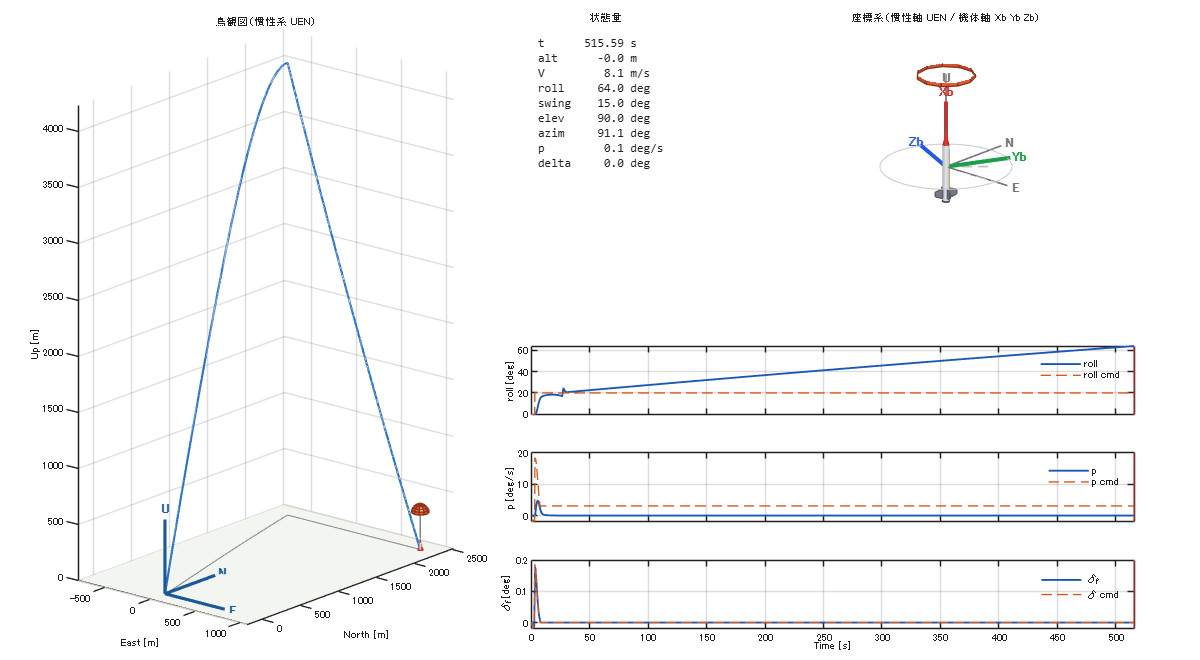

workshop_animate(simOut_rocket_6dof, "PlaybackSpeed", 10, "FrameRate", 8)